# Cross-WLF Viscosity Model Fitting

## **Viscosity data, **$\eta
$**(**$\dot\gamma
$,T):

*Find the coefficients of Cross-WLF that fit the following curves for **Polystyrene (PS)**:*

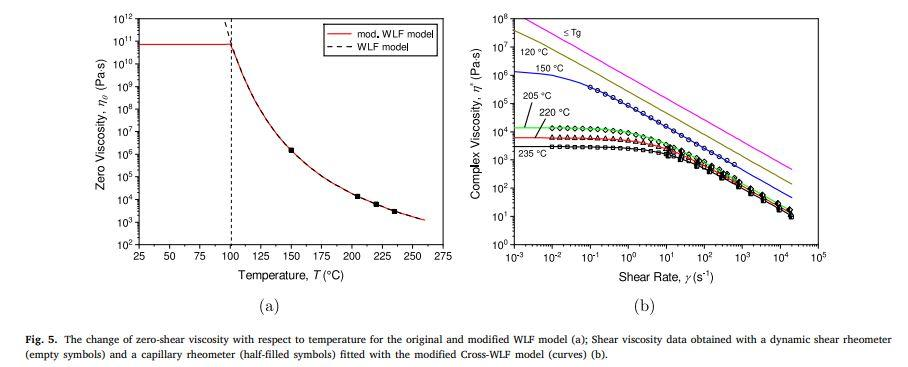

*(Kattinger et al., 2021).*

#### **Cross-WLF Model:**


$$\eta (\dot\gamma,T)=\frac{\eta_o(T)}{1+\left [\frac{\eta_0(T)\dot\gamma}{\tau*}\right ]^{1-n}}$$



$$\eta_0(T)=D_1 exp \left [\frac{-A_1(T-D_2)}{A_2+(T-D_2)} \right]$$


#### **Master Curve: TTS (Time Temperature Superposition):**

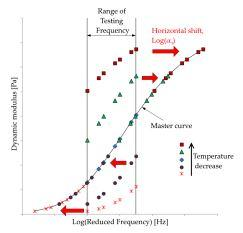


$$\eta (\dot\gamma,T)=\frac{\eta_o(T)}{1+\left [\frac{\eta_0(T)\dot\gamma a_T}{\tau*}\right ]^{1-n}} \left[\frac{1}{a_T}\right]$$


#### **Data sampling:**

% CURVE 1 235ºC
s1 = [1.0000E-03 9.6730E-03 1.5648E-02 2.5620E-02 3.7650E-02 6.3140E-02 9.6180E-02 1.6130E-01 2.4280E-01 4.1210E-01 6.1280E-01 9.5620E-01 1.5657E+00 2.3850E+00 4.0490E+00 6.1670E+00 1.0985E+01 1.5199E+01 2.3720E+01 3.8370E+01 6.1330E+01 1.3730E+02 2.9290E+02 8.1420E+02 1.6160E+03 3.6620E+03 9.7000E+03 1.8800E+04];
mu1 = [2.9300E+03 2.9800E+03 2.8860E+03 2.8860E+03 2.9820E+03 2.7950E+03 2.7960E+03 2.7960E+03 2.6210E+03 2.6650E+03 2.6220E+03 2.5390E+03 2.4590E+03 2.2680E+03 1.9610E+03 1.7520E+03 1.4660E+03 1.2678E+03 1.0613E+03 8.4640E+02 6.8600E+02 3.7110E+02 2.3980E+02 1.0686E+02 6.4740E+01 3.6760E+01 1.7190E+01 1.1293E+01];
T1 = (235+273.15)*ones(1,28);

% CURVE 2 220ºC. REFERENCE TEMPERATURE.
s2 = [1.0207E-03 9.9070E-03 1.5458E-02 2.5010E-02 3.9020E-02 6.3120E-02 9.8500E-02 1.5744E-01 2.4860E-01 3.9270E-01 6.2760E-01 9.7940E-01 1.5843E+00 2.4430E+00 3.9520E+00 6.0930E+00 9.6230E+00 2.0780E+01 4.0260E+01 1.0411E+02 2.1950E+02 5.7440E+02 2.8100E+03 1.4777E+04];
mu2 = [6.0720E+03 5.9740E+03 5.9760E+03 5.9770E+03 5.7880E+03 5.9790E+03 5.9800E+03 5.8850E+03 5.4290E+03 5.2570E+03 5.1730E+03 4.6950E+03 4.4020E+03 4.0610E+03 3.3990E+03 2.9870E+03 2.3820E+03 1.5900E+03 1.1888E+03 6.3280E+02 3.5940E+02 1.7080E+02 5.5080E+01 1.4870E+01];
T2 = (220+273.15)*ones(1,24);

% CURVE 3 205ºC
s3 = [1.0453E-03 9.9050E-03 1.5831E-02 2.4410E-02 4.0930E-02 6.0150E-02 9.9670E-02 1.5741E-01 2.4860E-01 3.9730E-01 6.1260E-01 1.0152E+00 1.6230E+00 2.4720E+00 3.8570E+00 6.2400E+00 9.9750E+00 1.6530E+01 3.9300E+01 6.3580E+01 1.0411E+02 2.4750E+02 6.3240E+02 1.7160E+03 8.3960E+03 1.7490E+04];
mu3 = [1.3620E+04 1.3420E+04 1.2990E+04 1.3200E+04 1.3210E+04 1.2381E+04 1.2383E+04 1.1798E+04 1.1241E+04 1.0885E+04 9.8800E+03 9.1140E+03 7.7540E+03 6.4910E+03 5.5230E+03 4.4760E+03 3.4000E+03 2.5830E+03 1.5400E+03 1.1512E+03 7.8090E+02 4.0900E+02 2.0410E+02 9.5450E+01 2.8850E+01 1.6380E+01];
T3 = (205+273.15)*ones(1,26);

% CURVE 4 150ºC
s4 = [1.0315E-03 2.4520E-03 5.4220E-03 9.8930E-03 2.7170E-02 1.0078E-01 1.5170E-01 2.5140E-01 9.9040E-01 2.4710E+00 4.0460E+00 1.0092E+01 2.5170E+01 6.2050E+01 1.5478E+02 4.0030E+02 1.1398E+03 4.6000E+03 1.9480E+04];
mu4 = [1.2628E+06 1.2033E+06 1.0923E+06 1.0077E+06 6.8370E+05 3.6400E+05 2.7650E+05 2.0670E+05 8.2250E+04 4.2390E+04 2.9700E+04 1.5060E+04 7.2760E+03 3.6300E+03 1.8110E+03 8.8930E+02 3.9620E+02 1.3630E+02 4.5390E+01];
T4 = (150+273.15)*ones(1,19);

Each of the variables is concatenated into a single array:

s_ex = [s1 s2 s3 s4];
mu_ex = [mu1 mu2 mu3 mu4];
T_ex = [T1 T2 T3 T4];

Experimental Data Plot:

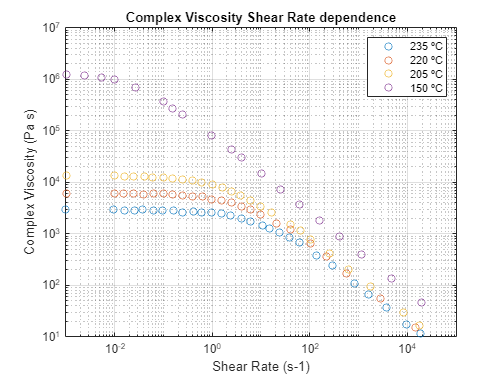

figure
loglog(s1,mu1,'o',s2,mu2,'o',s3,mu3,'o',s4,mu4,'o')
xlim([1e-03 1e05])
title('Complex Viscosity Shear Rate dependence')
ylabel('Complex Viscosity (Pa s)')
xlabel('Shear Rate (s-1)')
legend({'235 ºC','220 ºC','205 ºC','150 ºC'})
grid on

**MASTER CURVE CONSTRUCTION:**

 % Curve 1: Reduced Shear Strain Rate and Reduced Viscosity.
at1 =0.49 ; % at1 235ºC  
    s1_r = s1*at1;
    mu1_r = mu1/at1;
    
 % Curve 2: REFERENCE TEMPERATURE. DO NOT CHANGE.
at2 = 1; % at3 220ºC
    s2_r = s2*at2;
    mu2_r = mu2/at2;
    
% Curve 3: Reduced Shear Strain Rate and Reduced Viscosity.
at3 =2.22; % at3 205ºC
    s3_r = s3*at3;
    mu3_r = mu3/at3;

% Curve 4: Reduced Shear Strain Rate and Reduced Viscosity.
at4 =235; % at4 150ºC
    s4_r = s4*at4;
    mu4_r = mu4/at4;

**MASTER CURVE CONSTRUCTION: TTS METHOD**

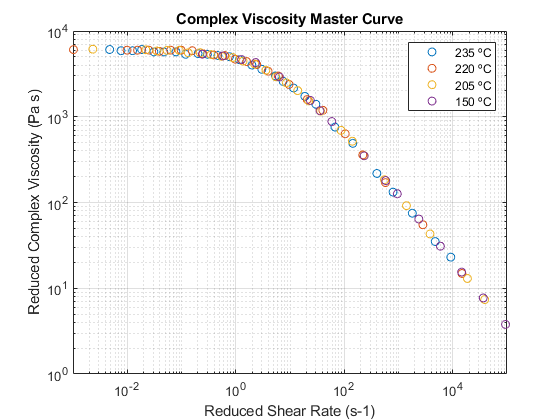

figure
loglog(s1_r,mu1_r,'o',s2,mu2,'o',s3_r,mu3_r,'o',s4_r,mu4_r,'o')
xlim([1e-03 1e05])
title('Complex Viscosity Master Curve')
ylabel('Reduced Complex Viscosity (Pa s)')
xlabel('Reduced Shear Rate (s-1)')
legend({'235 ºC','220 ºC','205 ºC','150 ºC'})
grid on

**WLF FITTING: **coefficients adjusted with shift coefficient (at) - temperature (T) curve. 

Tt_t = [235 220 205 150]+273.15; 
at_t = [0.49 1 2.22 235];

mdlfun = 'y~exp((-b1*(x-493.15))/(b2+x-493.15))'; % WLF model (y->at)=f(x->T). Tref = 493.15 K.
opts.MaxIter = 10000;
opts.TolFun = 1e15;
opts.TolX = 1e-15;
beta0 = [1 90];
mdl = fitnlm (Tt_t,at_t,mdlfun,beta0)

mdl = Nonlinear regression model:
    y ~ exp(( - b1*(x - 493.15))/(b2 + x - 493.15))

Estimated Coefficients:
          Estimate      SE       tStat       pValue  
          ________    _______    ______    __________

    b1     9.2526     0.18387    50.322    0.00039466
    b2     188.63      2.3576    80.012    0.00015617


Number of observations: 4, Error degrees of freedom: 2
Root Mean Squared Error: 0.0115
R-Squared: 1,  Adjusted R-Squared 1
F-statistic vs. zero model: 2.07e+08, p-value = 4.83e-09

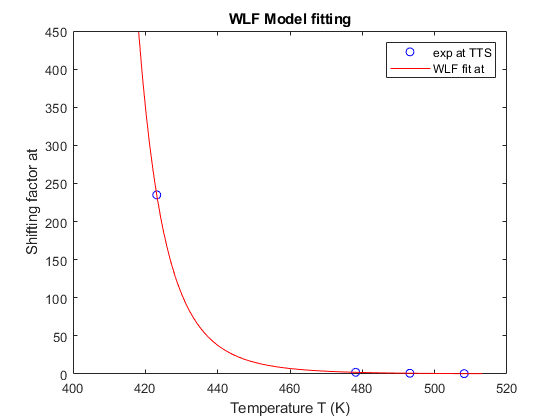

S = table2struct(mdl.Coefficients(:,1),"ToScalar",true);

% WLF COEFFICIENTS:
C1 = S.Estimate(1);
C2 = S.Estimate(2);
Tr = 273.15+220;
mu0 = mu2(1);

% WLF Fitting Plot:
Ti = 145+273.15:240+273.15;
at= exp((-C1.*(Ti-Tr))./(C2+Ti-Tr));
plot(Tt_t,at_t,'bo')
hold on
plot(Ti,at,'r-')
hold off
legend({'exp at TTS','WLF fit at'})
title('WLF Model fitting')
xlabel('Temperature T (K)')
ylabel('Shifting factor at')
legend({'exp at TTS','WLF fit at'})

**CROSS-WLF FITTING: ** Fitting is done using the Master Curve. Hence T=Tref and mu0=1, which allows to simplify the equation.

s_r = [s1_r s2_r s3_r s4_r];
mu_r = [mu1_r mu2_r mu3_r mu4_r];

% Cross Equation Fit:
[xData, yData] = prepareCurveData( s_r, mu_r );

% Set up fittype and options.
ft = fittype( '6072/(1+(6072*x/tau)^(1-n))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Algorithm = 'Levenberg-Marquardt';
opts.DiffMaxChange = 0.001;
opts.Robust = 'LAR';
opts.Display = 'Off';
opts.StartPoint = [0.959492426392903 0.655740699156587];
opts.TolFun = 1e-15;
opts.TolX = 1e-15;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      General model:
     fitresult(x) = 6072/(1+(6072*x/tau)^(1-n))
     Coefficients (with 95% confidence bounds):
       n =      0.2557  (0.2523, 0.2591)
       tau =   3.288e+04  (3.266e+04, 3.31e+04)

gof = struct with fields:
           sse: 3.4227e+04
       rsquare: 0.9999
           dfe: 95
    adjrsquare: 0.9999
          rmse: 18.9811


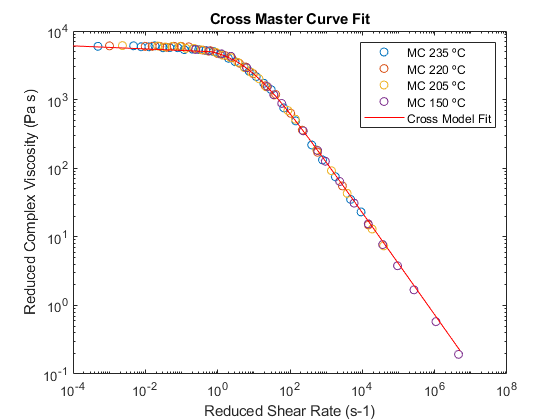

% CROSS COEFFICIENTS:
n = fitresult.n;
tau = fitresult.tau;

% CROSS MASTER CURVE Fitting Plot:
si = 1E-04:0.7:5E06;
mu_t= 6072./(1+(6072.*si./tau).^(1-n));

figure
loglog(s1_r,mu1_r,'o',s2,mu2,'o',s3_r,mu3_r,'o',s4_r,mu4_r,'o')
hold on
loglog(si,mu_t,'r-')
hold off

title('Cross Master Curve Fit')
ylabel('Reduced Complex Viscosity (Pa s)')
xlabel('Reduced Shear Rate (s-1)')
legend({'MC 235 ºC','MC 220 ºC','MC 205 ºC','MC 150 ºC','Cross Model Fit'})

% CROSS-WLF COEFFICIENTS:
n;
tau;
A1 = C1;
A2 = C2;
D2 = Tr;
D1 = mu0;

### **Test:**

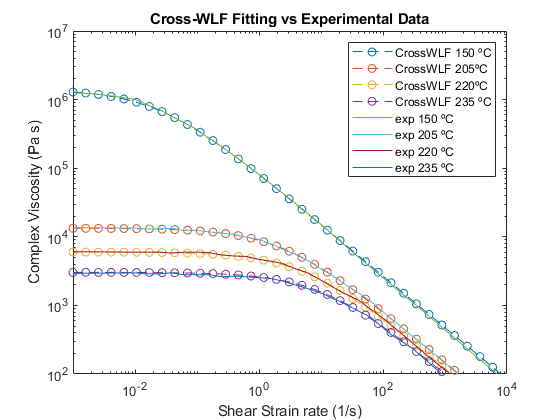

s_test= logspace(-03,05,40);

% 150 ºC
T150 = (150+273.15)*ones(1,40);
mu150 = 6000.*exp((-9.2526.*(T150-493.15))./(188.63+(T150-493.15)))./(1+(s_test.*6000.*exp((-9.2526.*(T150-493.15))./(188.63+(T150-493.15)))./3.354e04).^(1-0.2489));

loglog(s_test,mu150,'--o')
hold on

% 205 ºC
T205 = (205+273.15)*ones(1,40);
mu205 = 6000.*exp((-9.2526.*(T205-493.15))./(188.63+(T205-493.15)))./(1+(s_test.*6000.*exp((-9.2526.*(T205-493.15))./(188.63+(T205-493.15)))./3.354e04).^(1-0.2489));

loglog(s_test,mu205,'--o')
hold on

% 220 ºC
T220 = (220+273.15)*ones(1,40);
mu220 = 6000.*exp((-9.2526.*(T220-493.15))./(188.63+(T220-493.15)))./(1+(s_test.*6000.*exp((-9.2526.*(T220-493.15))./(188.63+(T220-493.15)))./3.354e04).^(1-0.2489));

loglog(s_test,mu220,'--o')
hold on

% 235 ºC
T235 = (235+273.15)*ones(1,40);
mu235 = 6000.*exp((-9.2526.*(T235-493.15))./(188.63+(T235-493.15)))./(1+(s_test.*6000.*exp((-9.2526.*(T235-493.15))./(188.63+(T235-493.15)))./3.354e04).^(1-0.2489));

loglog(s_test,mu235,'--o')
hold on

% Experimental data 150ºC
plot(s4, mu4)
hold on

% Experimental data 205ºC
plot(s3, mu3)
hold on

% Experimental data 220ºC
plot(s2, mu2)
hold on

% Experimental data 235ºC
plot(s1, mu1)
hold off

xlim([1e-03 1e04])
ylim([1e2 1e07])
legend({'CrossWLF 150 ºC','CrossWLF 205ºC','CrossWLF 220ºC','CrossWLF 235 ºC','exp 150 ºC','exp 205 ºC','exp 220 ºC','exp 235 ºC'}, 'Location', 'NorthEast')
title('Cross-WLF Fitting vs Experimental Data')
xlabel('Shear Strain rate (1/s)')
ylabel('Complex Viscosity (Pa s)')